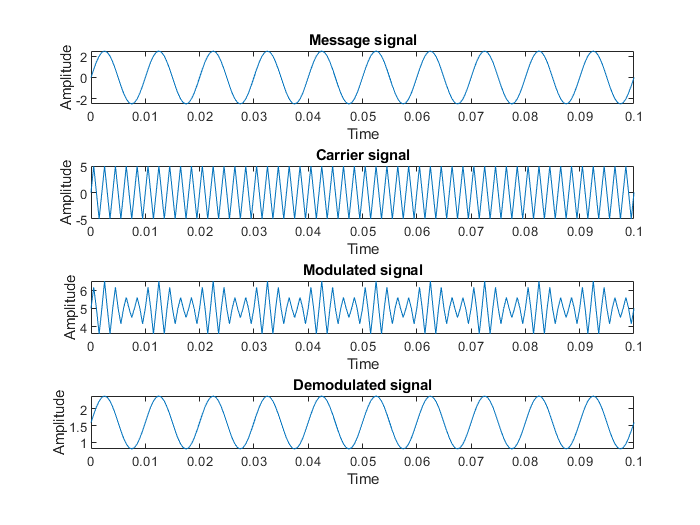

clc; clear all; clf;

Am = 2.5;
Ac = 5;
fm = 100;
fc = 4500;
phi = 0;
t = 0 : 0.0005 : 0.1; 
m = Am / Ac;
wc1 = 2*pi*fm;
wc2 = 2*pi*fc;

Modulating = Am * sin(wc1*t + phi);
Carrier = Ac * sin(wc2*t + phi);
Modulated = Ac + (1 + m*sin(2*pi*fm*t + phi)) .* sin(2*pi*fc*t + phi);
Demodulated = (1/pi)*(Ac+Modulating);

subplot(4, 1, 1);
plot(t, Modulating);
title('Message signal');
xlabel('Time');
ylabel('Amplitude')

subplot(4, 1, 2);
plot(t, Carrier);
title('Carrier signal');
xlabel('Time');
ylabel('Amplitude')

subplot(4, 1, 3);
plot(t, Modulated);
title('Modulated signal');
xlabel('Time');
ylabel('Amplitude')

subplot(4, 1, 4);
plot(t, Demodulated);
title('Demodulated signal');
xlabel('Time');
ylabel('Amplitude')